# Chirp Detection

This file will serve as a coding whiteboard of sorts as I tease out a chirp detection algorithm

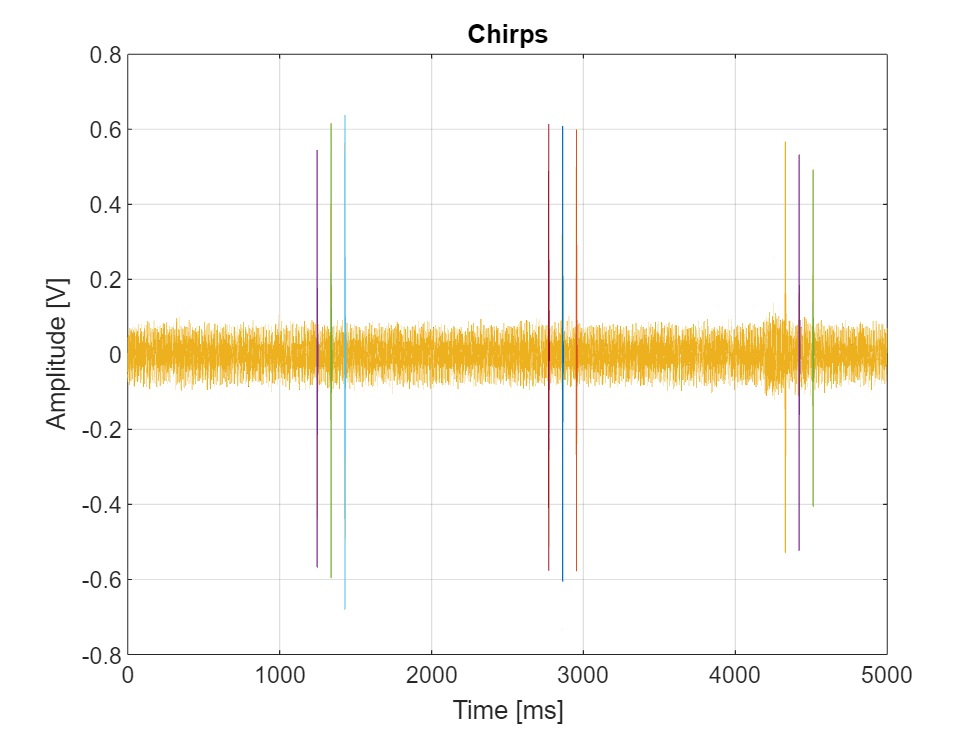

datatimetable = importdata("Chirps.mat");

time = seconds(datatimetable.Time) * 1000;
data = datatimetable.Dev1_ai1;
data = normalize(data, "center", "mean"); % Center data at 0 V

figure(1);
plot(time, data)
title('Chirps')
xlabel('Time [ms]')
ylabel('Amplitude [V]')
grid on;
hold on;

sample_rate = 250000;

% Find peaks in data taken at a sample_rate that are at least 5 ms apart
% and 0.2 V in amplitude
[peaks, peak_indices] = findpeaks(data, 'MinPeakDistance', round(0.005 * sample_rate), 'MinPeakHeight', 0.2);

number_mics = size(data, 2);
window_duration = round(0.006 * sample_rate) + 1;

% Preallocate the peak_windows array
peak_window = zeros(numel(peaks), window_duration, number_mics);

% Create the time values for each sample in peak_windows
time_values = zeros(numel(peaks), window_duration, number_mics);

for i = 1:number_mics
    for j = 1:numel(peaks)
        % Start 1 ms before the chirp and continue for 5 ms after
        window_start = peak_indices(j) - round(0.001 * sample_rate);
        window_end = peak_indices(j) + round(0.005 * sample_rate);

        % Check if the window indices are within the data range
        if window_start >= 1 && window_end <= numel(data)
            peak_window(j, :, i) = data(window_start:window_end, i)';
            
            % Calculate the time values for the corresponding samples
            time_values(j, :, i) = (window_start:window_end) / sample_rate * 1000;
        end
    end
end

for i=1:numel(peaks)
    plot(time_values(i,:,1),peak_window(i,:,1))
end

Got it! This file will become a plotting paradigm, as I will rewrite the paradigm as a function

size(peak_window)

ans =            9        1501


size(time_values)

ans =            9        1501


disp(peaks)

    0.5446
    0.6152
    0.6381
    0.6140
    0.6087
    0.5984
    0.5671
    0.5321
    0.4924



size(peak_indices)

ans =      9     1
